# 姓名：贾林轩   学号：1853688

## 栅格地图作业

### 1.建立map

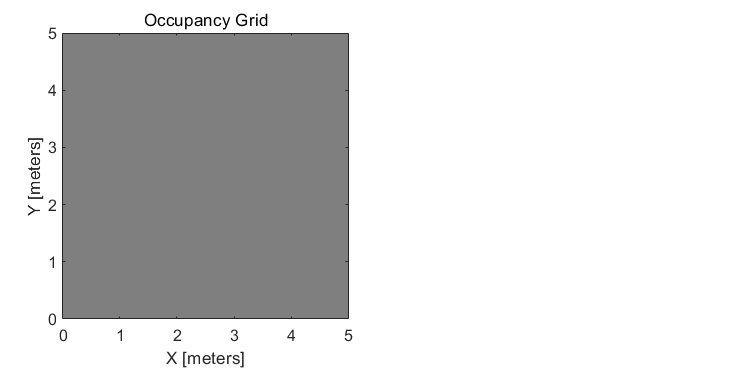

map = occupancyMap(5,5,1); %建立地图，（长，宽，分辨率）
x = [2;4];
y = [2;4];
pvalues = [0.2 0.8]; 

figure(1);set(gcf,'Position',[10,10,600,300]);
tiledlayout(1,2,"Padding","compact","TileSpacing","compact")
nexttile; show(map)

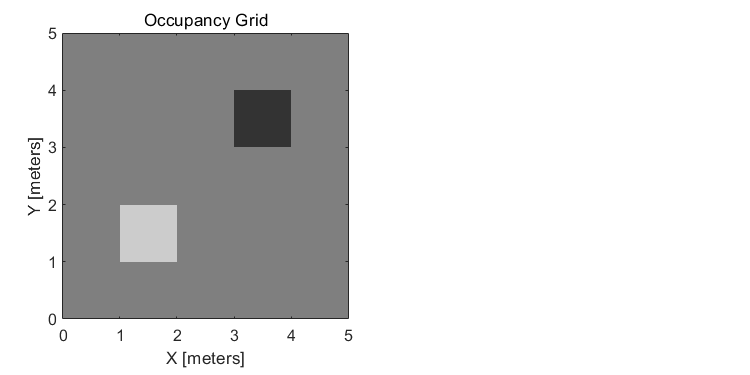

updateOccupancy(map,[x y],pvalues) % 使用 p 值中的特定值更新世界位置的占用率。

figure(2);  set(gcf,'Position',[10,10,600,300]);
tiledlayout(1,2,"Padding","compact","TileSpacing","compact")
nexttile; show(map)

### 2.利用Occupancy函数计算概率

index = 2;
getOccupancy(map,[x(index),y(index)],"local")

ans = 0.8000

updateOccupancy(map,[x(index) y(index)],pvalues(2));
getOccupancy(map,[x(index),y(index)],"local")

ans = 0.9412

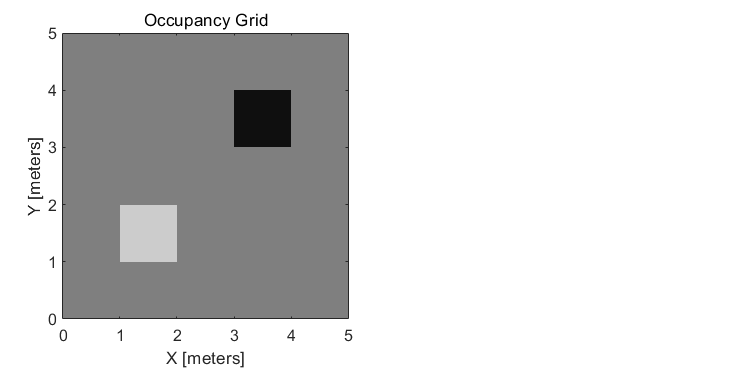

show(map)

updateOccupancy(map,[x(index) y(index)],pvalues(2));
getOccupancy(map,[x(index),y(index)],"local")

ans = 0.9846

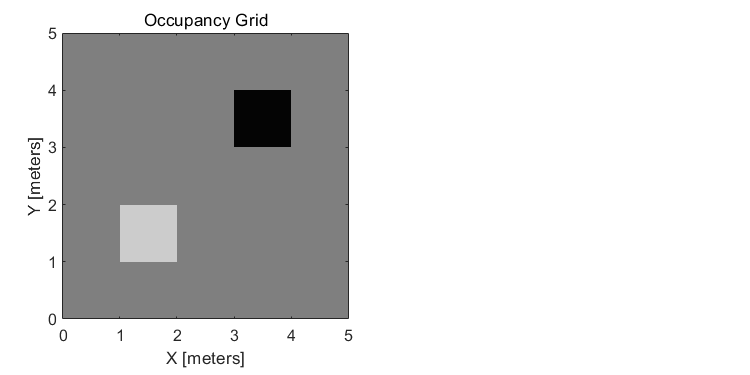

show(map)

### 3.利用公式计算概率

L3=log(8/2*8/2*8/2)

L3 = 4.1589

P1=1-1/(1+exp(0-log(0.8/(1-0.2))))

P1 = 0.5000

P2=1-1/(1+exp(0-log(0.25)-log(0.25)))

P2 = 0.9412

P3=1-1/(1+exp(0-log(0.25)-log(0.25)-log(0.25)))

P3 = 0.9846

P=1-1/(1+exp(L3))

P = 0.9846